%% Import data from text file
% Script for importing data from the following text file:
%
%    filename: /Users/ldana/Documents/1140/LCR Data/Data_data_data_data_data_data_data_data/Lab 4-5 Data.csv
%
% Auto-generated by MATLAB on 09-Dec-2021 14:40:18
close all; clear all;
%% Set up the Import Options and import the data
opts = delimitedTextImportOptions("NumVariables", 3);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["LatestTimes", "LatestPotentialV", "Run1Times"];
opts.VariableTypes = ["double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
%tbl = readtable("/Users/ldana/Documents/1140/LCR Data/Data_data_data_data_data_data_data_data/Lab 4-5 Data.csv", opts);
tbl = readtable("/Users/ldana/Documents/1140/LCR Data/Data_data_data_data_data_data_data_data/NewFile4.csv", opts);


%% Convert to output type
LatestTimes = tbl.LatestTimes;
LatestPotentialV = tbl.LatestPotentialV;
Run1Times = tbl.Run1Times;

%% Clear temporary variables
clear opts tbl




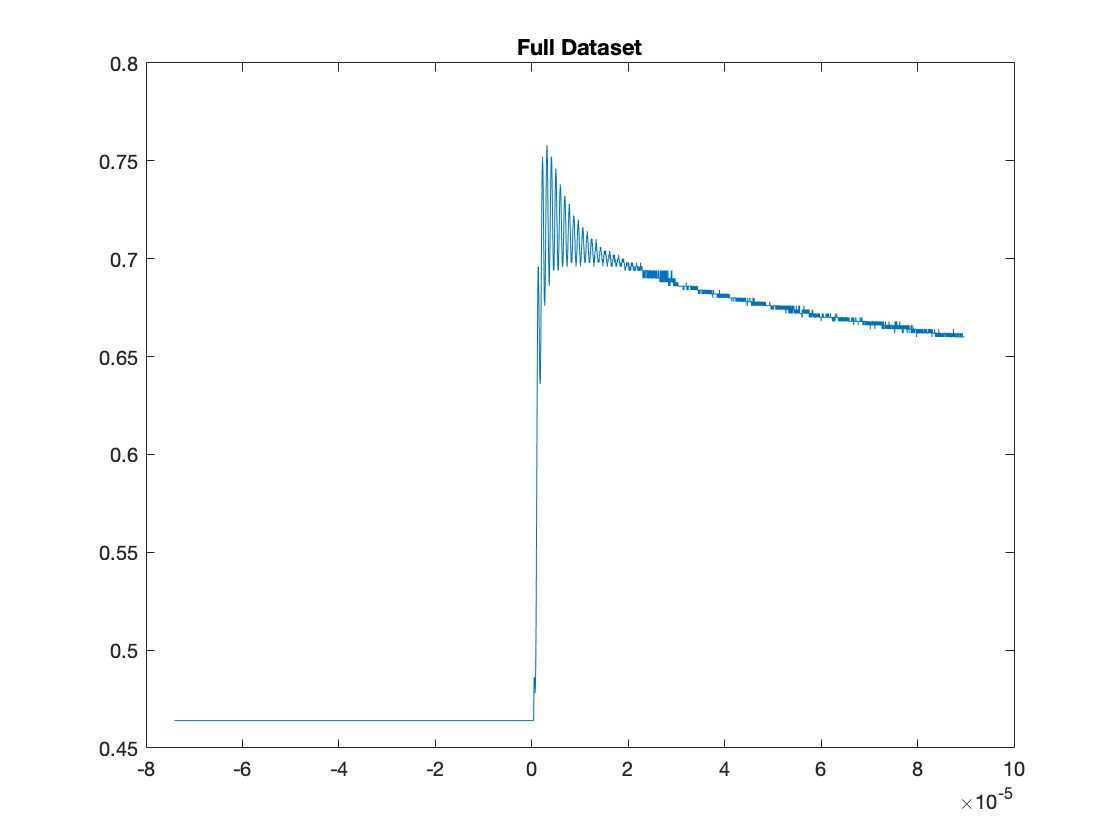


%I imported data by double clicking on it then importing it as a Column
%Vector

T = LatestTimes;
YCH = LatestPotentialV;

% Moved to the end because I was dumb and used L again later
% c = 3.3e-6; %Capcitor you used in F 
% L = 1e-3; %Inductance in Henries 
% R = 51; %resistor used in Ohms


figure()
plot(T, YCH)
title('Full Dataset')


clear LatestPotentialV LatestTimes Run1Times

After plotting I can see that everything before the 0 is useless, so I'm going to cut off my data before then. 

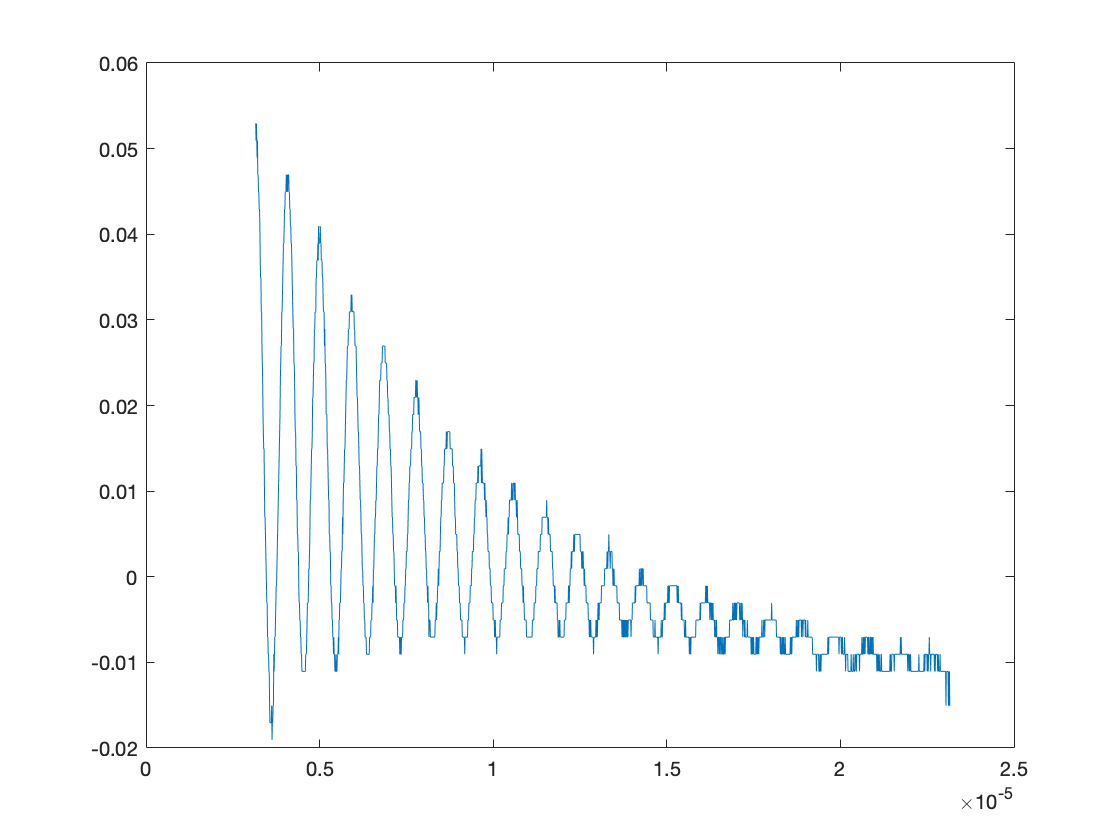

[mm,xx] = max(YCH); %This finds max for the data
hh = 2000; %Cut down the amount we look @

%To account for DC offset (somewhat lol) 
YCH_NODC = YCH(xx:xx+hh) - mean(YCH(xx:xx+hh));


G = figure();
plot(abs(T(xx:xx+hh)), YCH_NODC)
saveas(G, 'Spectrum of LCR', 'jpg')

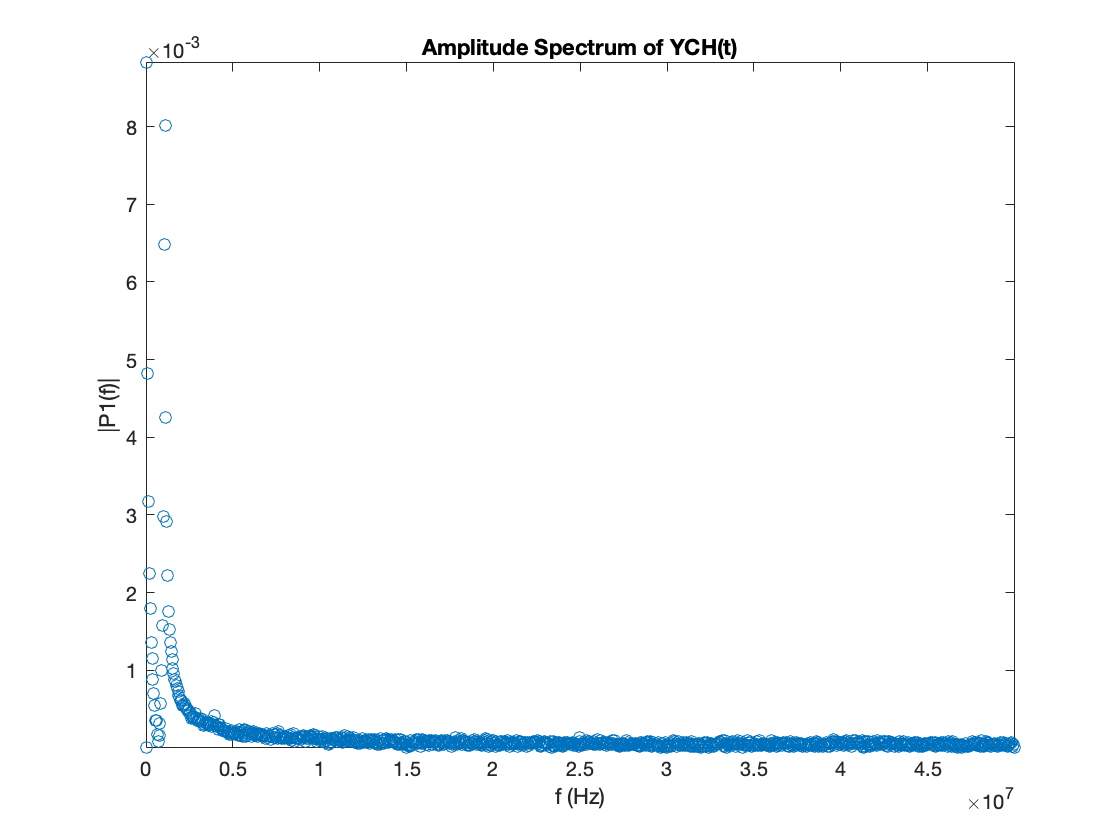


fourier = fft(YCH_NODC);

timeDif =abs( abs(T(xx))-abs(T(xx+1)));
Fs = 1/timeDif;            % Sampling frequency                    
Period = 1/Fs;             % Sampling period       
L = length(T(xx:xx+hh));             % Length of signal
t = (0:L-1)*Period;        % Time vector

Y = fourier; 
P2 = abs(Y/L);
%P1 = P2(1:L/2+1);
P1 = P2(1:round(L/2)); 
P1(2:end-1) = 2*P1(2:end-1);

f = Fs*(0:(L/2))/L;
H = plot(f,P1, 'o'); 
%findpeaks(P1)
axis tight
title('Amplitude Spectrum of YCH(t)')
xlabel('f (Hz)')
ylabel('|P1(f)|')


%saveas(H, 'FFT Spectrum of LCR', 'jpg')

clear mm xx timeDif Fs  Period  L Y P2 hh  t fourier

%THIS IS MOSTLY JUST THE DC OFFSET YOU ALL HAVE IT
[mm,kk] = max(P1); 

if kk == 1
%REAL FREQUENCY WE CARE ABOUT
    [Amplitude, ii ] = max(P1(kk+1:end));
    freq = f(ii)
else 
    freq = f(kk)
end

freq = 4.9976e+04



% 10^6 is mega Hz


Working from theory explained here [http://hyperphysics.phy-astr.gsu.edu/hbase/electric/rlcser.html](http://hyperphysics.phy-astr.gsu.edu/hbase/electric/rlcser.html)

c = 3.3e-6; %Capcitor you used in F 
L = 1e-3; %Inductance in Henries 
R = 51; %resistor used in Ohms


omega = 2*pi*freq

omega = 3.1401e+05

%Then Xc and XL can be found

Xc = 1 / omega * c; 
Xl = omega * L; 

%Impedence 
Z = sqrt(R^2 + ((Xl - Xc)^2));

%Phase 
P = tanh((Xl - Xc )/ R);


%Theory Omega
TheoryOmega = 1/(sqrt(L*c))

TheoryOmega = 1.7408e+04

TheoryFreq = TheoryOmega/(2*pi)

TheoryFreq = 2.7705e+03


freq

freq = 4.9976e+04

% Uncertainty test 

